# Задание № 5.2

## **Решение задачи Коши для дифференциальных уравнений второго и более высокого порядка. Дифференциальное уравнение с параметрами *****a, b, c, ******d*****.**

**1. Решить символьно с помощью **`dsolve`** дифференциальное уравнения второго порядка**

Дано линейное однородное дифференциальное уравнение второго порядка     следующего вида

                                                   $a∗x\prime \prime +b∗x\prime +c∗x=0$**    (1) **

при заданных начальных условиях

                                                               $x_0 =1,{x\prime }_0 =0$          **(2)**

и произвольных параметрах  ***a****,* ***b****,* ***c***  .

Решение уравнений начинать с символьного метода, используя решатель dsolve, а если он не даст явных результатов, переходить к численному методу, применяя решатель ode23.

*Поскольку * *уравнение (1) имеет явное решение в аналитическом*  *виде и численный метод для него не потребуется, то в данном задании нужно не только получить формальное решение, но и выполнить небольшое исследование, чтобы разобраться, как на вид решения (его график) влияют начальные условия* *и величины **a**, **b**, **c**.*

- *Предлагается при задании начальных значений рассмотреть 3 случая: *


$$ \begin{cases}
   x'_{0} \neq 0, x_{0} = 0;
   \\
  x'_{0} = 0, x_{0} \neq 0;
   \\
   x'_{0} = 0, x_{0} = 0.
 \end{cases}$$


- *При задании параметров **выбрать * *a:*

 
$$a\le 100;$$


- *b*  *рассмотреть в двух * *вариантах*:


$$\begin{cases}
     b = 0;
\\
     b \neq 0, b \leq 30.
\end{cases}$$


- *с*  *рассмотреть также*  *в двух вариантах:*


$$\begin{cases}
     c < 10;
\\
     c > 1000.
\end{cases}$$


Построить, применяя  функцию *fplot*, а также используя команду *subplot* ,  сравнительные графики  решения *x**(**t**) для разных значений параметров (*по два на каждом рисунке), указать величины параметров в заголовках и в подписях под графиками. На основании построенных графиков сделать вывод о влиянии начальных условий на частоту и период колебаний.

$$X(t) = \frac{\sqrt{800}\,{\mathrm{e}}^{-\frac{\sqrt{800}\,t\,\mathrm{i}}{100}}\,\mathrm{i}}{8}-\frac{\sqrt{800}\,{\mathrm{e}}^{\frac{\sqrt{800}\,t\,\mathrm{i}}{100}}\,\mathrm{i}}{8}$$

$$X(t) = \frac{\sqrt{144000}\,{\mathrm{e}}^{-\frac{\sqrt{144000}\,t\,\mathrm{i}}{60}}\,\mathrm{i}}{2400}-\frac{\sqrt{144000}\,{\mathrm{e}}^{\frac{\sqrt{144000}\,t\,\mathrm{i}}{60}}\,\mathrm{i}}{2400}$$

$$X(t) = -\frac{198\,\sqrt{1751}\,{\mathrm{e}}^{\frac{t\,\left(-25+\sqrt{1751}\,\mathrm{i}\right)}{198}}\,\mathrm{i}}{1751}+\frac{198\,\sqrt{1751}\,{\mathrm{e}}^{-\frac{t\,\left(25+\sqrt{1751}\,\mathrm{i}\right)}{198}}\,\mathrm{i}}{1751}$$

$$X(t) = -\frac{33\,\sqrt{659804}\,{\mathrm{e}}^{\frac{t\,\left(-14+\sqrt{659804}\,\mathrm{i}\right)}{132}}\,\mathrm{i}}{164951}+\frac{33\,\sqrt{659804}\,{\mathrm{e}}^{-\frac{t\,\left(14+\sqrt{659804}\,\mathrm{i}\right)}{132}}\,\mathrm{i}}{164951}$$

$$X(t) = \frac{5\,{\mathrm{e}}^{-\frac{\sqrt{800}\,t\,\mathrm{i}}{100}}}{2}+\frac{5\,{\mathrm{e}}^{\frac{\sqrt{800}\,t\,\mathrm{i}}{100}}}{2}$$

$$X(t) = \frac{5\,{\mathrm{e}}^{-\frac{\sqrt{144000}\,t\,\mathrm{i}}{60}}}{2}+\frac{5\,{\mathrm{e}}^{\frac{\sqrt{144000}\,t\,\mathrm{i}}{60}}}{2}$$

$$X(t) = -\frac{5\,\sqrt{1751}\,{\mathrm{e}}^{\frac{t\,\left(-25+\sqrt{1751}\,\mathrm{i}\right)}{198}}\,\left(25+\sqrt{1751}\,\mathrm{i}\right)\,\mathrm{i}}{3502}-\frac{5\,\sqrt{1751}\,{\mathrm{e}}^{-\frac{t\,\left(25+\sqrt{1751}\,\mathrm{i}\right)}{198}}\,\left(-25+\sqrt{1751}\,\mathrm{i}\right)\,\mathrm{i}}{3502}$$

$$X(t) = -\frac{5\,\sqrt{659804}\,{\mathrm{e}}^{\frac{t\,\left(-14+\sqrt{659804}\,\mathrm{i}\right)}{132}}\,\left(14+\sqrt{659804}\,\mathrm{i}\right)\,\mathrm{i}}{1319608}-\frac{5\,\sqrt{659804}\,{\mathrm{e}}^{-\frac{t\,\left(14+\sqrt{659804}\,\mathrm{i}\right)}{132}}\,\left(-14+\sqrt{659804}\,\mathrm{i}\right)\,\mathrm{i}}{1319608}$$

$$X(t) = 0$$

$$X(t) = 0$$

$$X(t) = 0$$

$$X(t) = 0$$

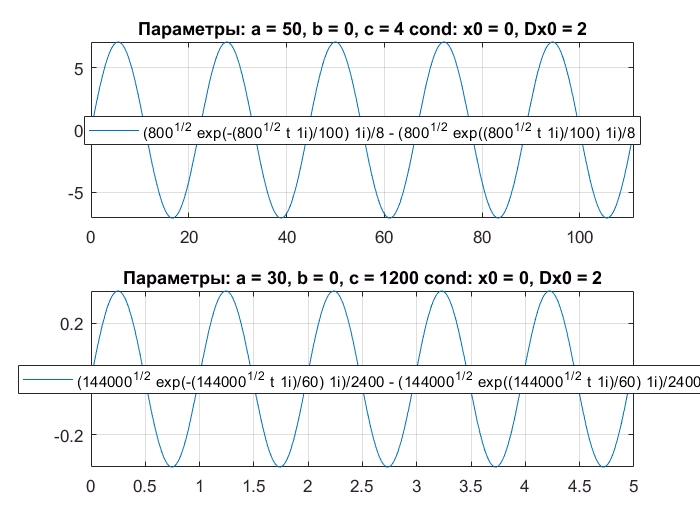

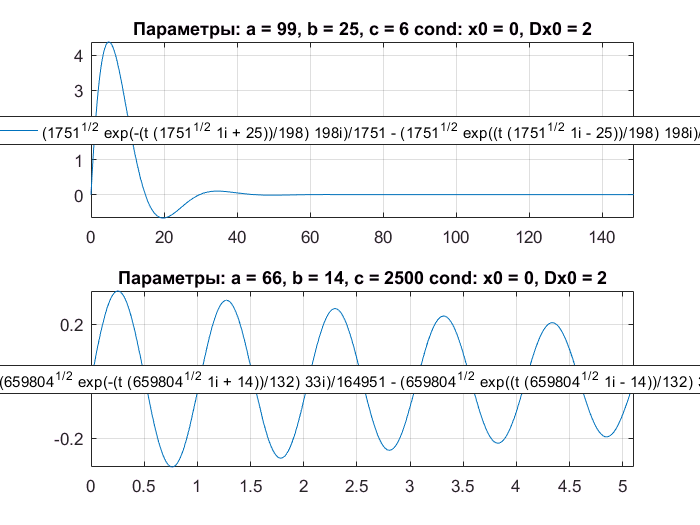

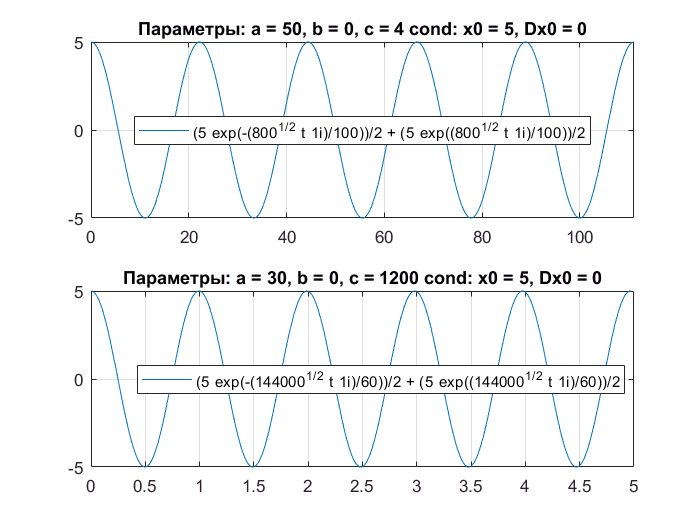

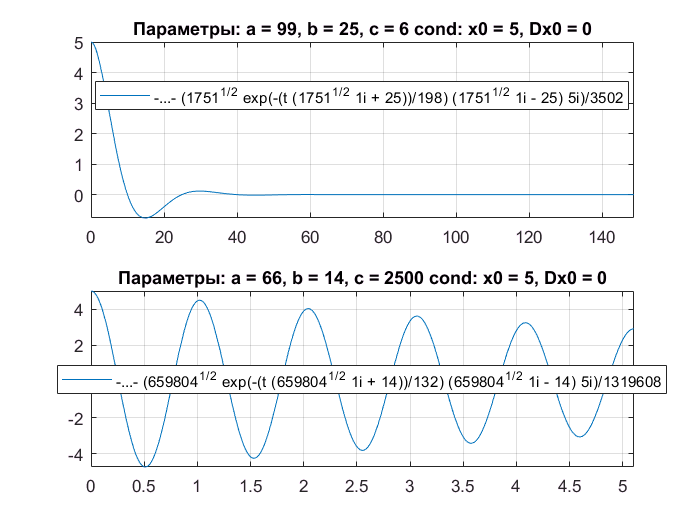

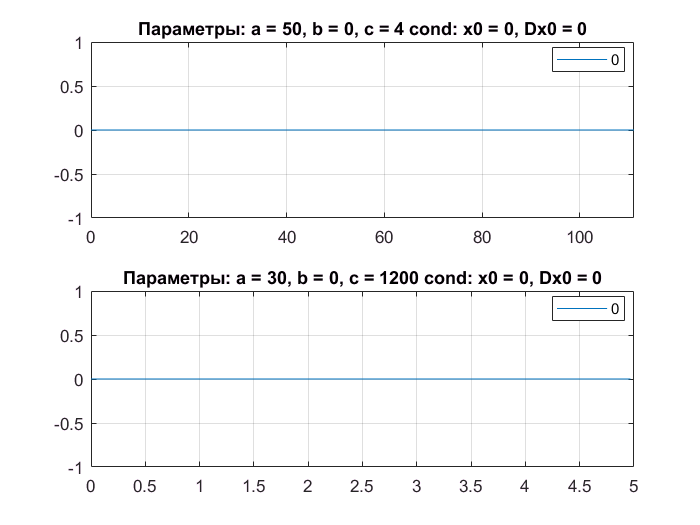

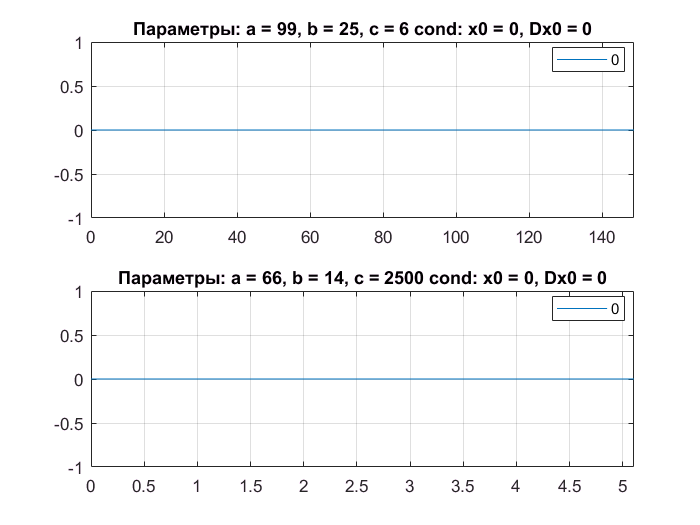

for i = 1:12
    syms x(t) a b c d
    eqn = a * diff(x,t,2) + b * diff(x,t) + c*x==0;
    Dx = diff(x,t);
    %--Задание начальных условий--
    if i <= 4
        cond = [x(0) == 0, Dx(0) == 2];
        cc = "; cond: x0 = 0, Dx0 = 2";
    elseif i > 4 && i <= 8
        cond = [x(0) == 5, Dx(0) == 0];
        cc = "; cond: x0 = 5, Dx0 = 0";
    else
        cond = [x(0) == 0, Dx(0) == 0];
        cc = "; cond: x0 = 0, Dx0 = 0";
    end

    %--Задание коэффициентов--
    if i == 1 || i == 5 || i == 9
        figure;
        subplot(2, 1, 1);
        a = 50;
        b = 0;
        c = 4;
    elseif i == 2 || i == 6 || i == 10
        subplot(2, 1, 2);
        a = 30;
        b = 0;
        c = 1200;
    elseif i == 3 || i == 7 || i == 11
        figure;
        subplot(2, 1, 1);
        a = 99;
        b = 25;
        c = 6;
    elseif i == 4 || i == 8 || i == 12
        subplot(2, 1, 2);
        a = 66;
        b = 14;
        c = 2500;
    end
    x(t) = dsolve(eqn,cond);
    X = subs(x)
    T = subs(4 * pi * a / sqrt(abs(b^2 - 4*a*c)));
    t = 5 * double(T);        %Вывод 5-ти волн
    tspan = [0 t];
    fplot(X, tspan);
    hold on;
    grid on;
    z = "Параметры: a = " + num2str(a) +...
    ", b = " + num2str(b) + ", c = " + num2str(c) + cc;
    title(z);
    legend('show', 'Location', 'Best')
end

**2. Решить символьно с помощью **`dsolve`** и численно с помощью   дифференциальное уравнение четвертого порядка.**

Рассмотреть **не**линейное  **не**однородное дифференциальное уравнение четвертого порядка     следующего вида

   
$$y^{\left(\mathrm{IV}\right)} +a∗y^{\left(\mathrm{III}\right)} +b∗y∗y^{\left(\mathrm{II}\right)} +c∗y^2 +d=0$$


при заданном векторе начальных условий  

 
$$y_0 =\left\lbrack 1\text{ }0\text{ }0\text{ }0\right\rbrack$$


Решать данную задачу символьно с помощью  `dsolve`  и численно, используя  решатель `ode23`. Значения параметрам a, b, c, d задать самостоятельно.

Построить *график* полученных  решений.   Используя блок `legend` , расшифровать линии для функции y(x) и трех ее производных, вставить заголовок  `title` гафика c названием «Решение диф. ур-я 4-го порядка. Функция и ее производные»

Вывести таблицу для 10 значений независимой переменной  x, равномерно распределенных на интервале [0 2]    (функция `linsolve`) и  соответствующих значений функции y(x), полученных с помощью команды `deval`.

%--Символьный метод--
clear;
syms y(t) a b c d;
eqn = diff(y, 4) + a * diff(y, 3) + b * y * diff(y, 2) + c * y.^2 + d == 0;
a = 16;
b = 245;
c = 4;
d = 60;
sol = dsolve(eqn);

%Т.к. символьное решение не может быть найдено,
%переходим к численным методам
[V] =  odeToVectorField(diff(y, 4) + a.*diff(y, 3) + b.*y.*diff(y, 2) + c.*y.^2 + d == 0);
M = matlabFunction(V,'vars', {'t','Y'});
tspan = [0 2];
y0 = [1 0 0 0];
sol =  ode45(M, tspan, y0);
t = linspace(0,2);
figure;
grid on;
hold on;
fplot(@(t) deval(sol, t, 1), [0, 2]);

fplot(@(t) deval(sol, t, 2), [0, 2], '--');

fplot(@(t) deval(sol, t, 3), [0, 2]);

fplot(@(t) deval(sol, t, 4), [0, 2]);

fplot(@(t) deval(sol, t, 5), [0, 2]);

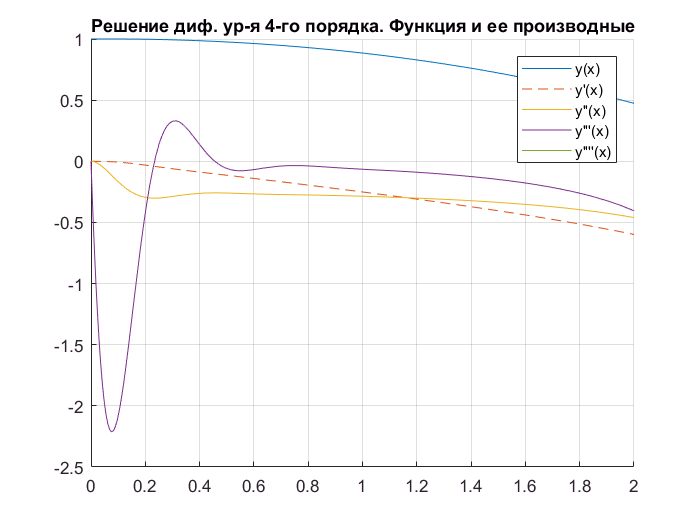

title('Решение диф. ур-я 4-го порядка. Функция и ее производные');
legend('y(x)', "y'(x)", "y''(x)", "y'''(x)", "y''''(x)");

T = table;
t = linspace(0, 2, 10);
T.X = t';
T.Y = deval(sol, t, 1)';
T.dY = deval(sol, t, 2)';
T

T = 10×3 table
       X          Y          dY    
    _______    _______    _________

          0          1            0
    0.22222    0.99725    -0.037908
    0.44444    0.98173    -0.099864
    0.66667    0.95308     -0.15845
    0.88889    0.91112     -0.21953
     1.1111    0.85533      -0.2831
     1.3333    0.78501     -0.35055
     1.5556    0.69912     -0.42358
     1.7778    0.59615     -0.50483
          2    0.47382     -0.59869
